# Homework 6

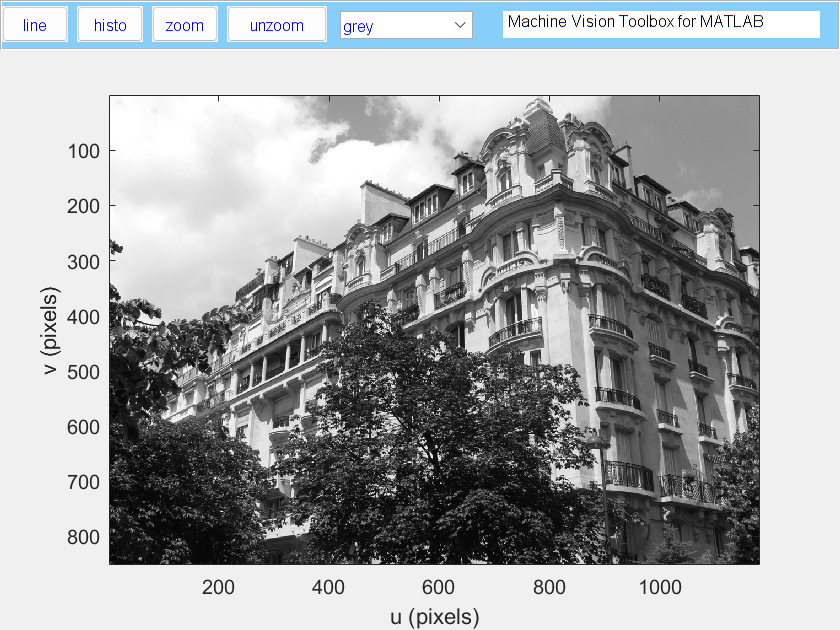

clc
clear
close all

% part 1
b1 = iread('building2-1.png','grey','double');
idisp(b1)

A = icorner(b1,'detector','harris','nfeat',200);

7550 corners found (0.8%),  200 corner features saved


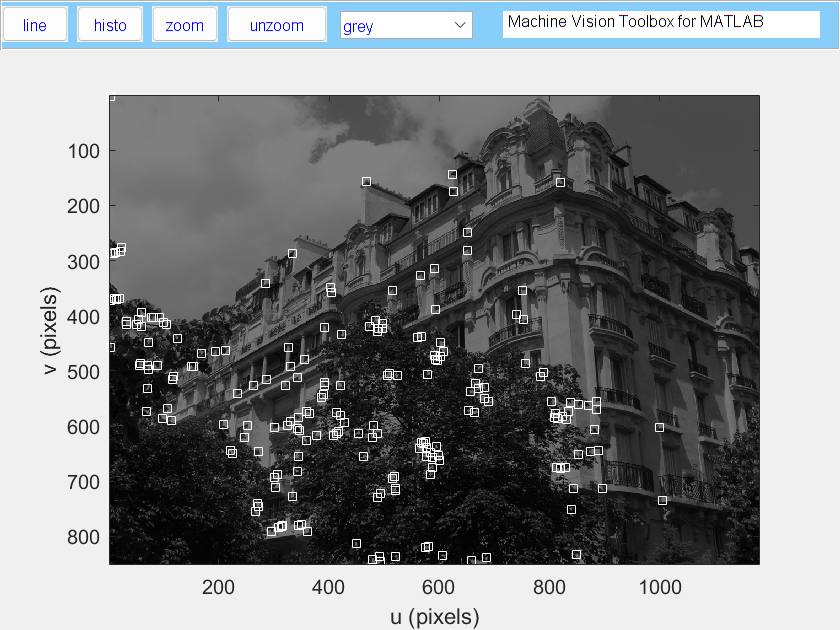

idisp(b1,'dark');
A.plot('ws');

B = icorner(b1,'detector','noble','nfeat',200);

7970 corners found (0.8%),  200 corner features saved


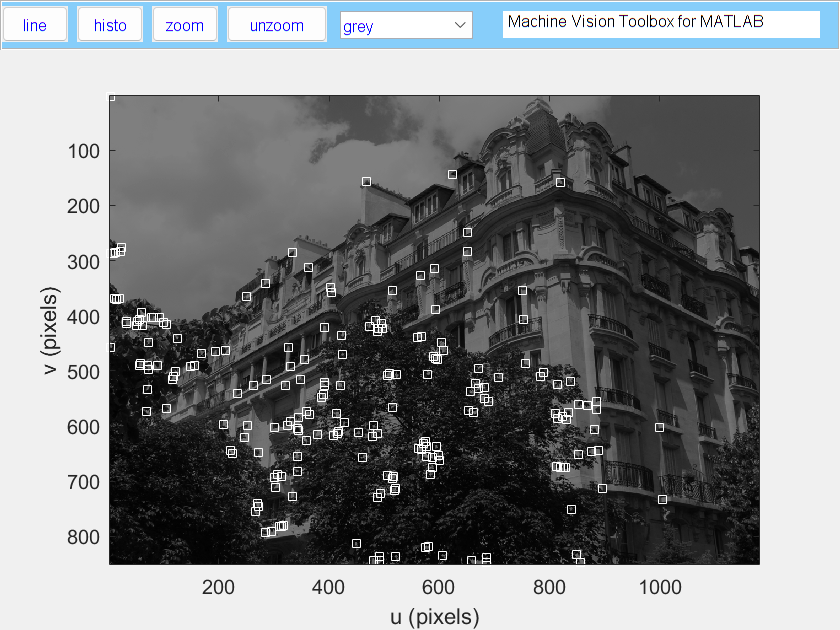

idisp(b1,'dark');
B.plot('ws');

C = icorner(b1,'detector','st','nfeat',200);

9614 corners found (1.0%),  200 corner features saved


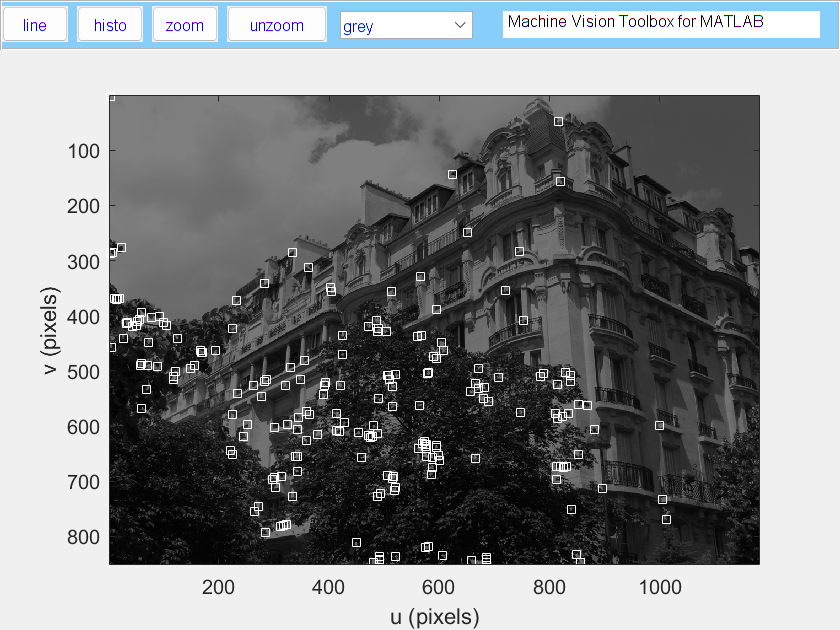

idisp(b1,'dark');
C.plot('ws');

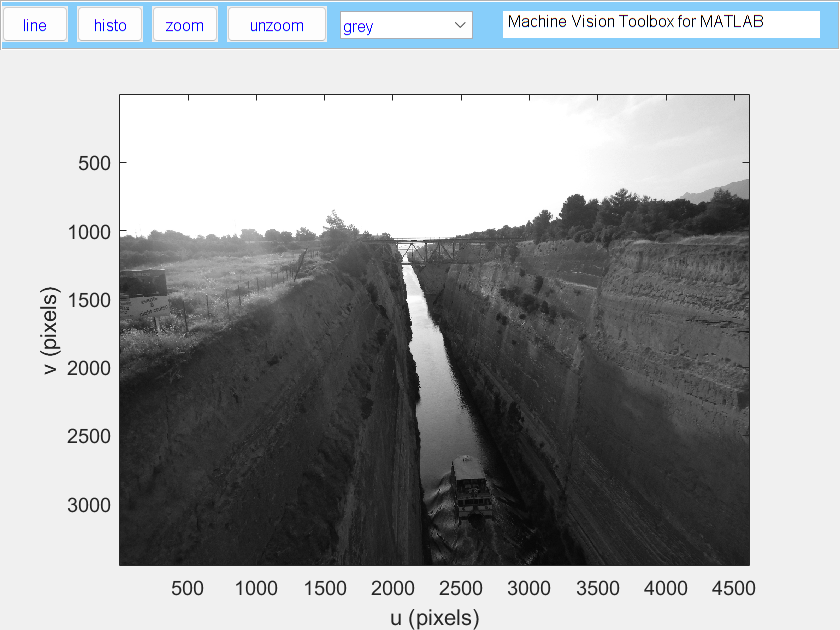

% part 2
im = iread('DSCN0986.JPG','grey','double');
idisp(im);

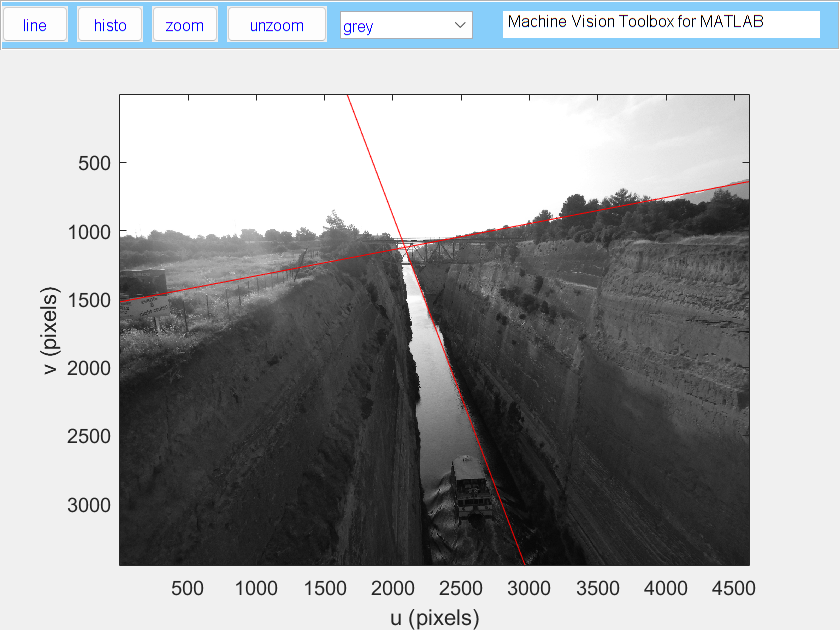

edges = icanny(im);
h = Hough(edges, 'suppress', 5);
lines = h.lines();
idisp(im);
lines(1:2).plot('r');